# **Volatility Modeling for Soft Commodities**

This example demonstrates a diverse set of statistical methods, machine learning techniques, and time-series models that you can apply broadly in the field of volatility modeling. Specifically, this example focuses on the analysis, modeling, and forecasting of volatility within the context of soft commodities.

Soft commodities refer to agricultural products that are grown rather than mined or extracted. These commodities are typically perishable and have a shorter shelf life compared to hard commodities like metals or energy resources. Soft commodities are highly influenced by uncertainties arising from climate change-induced shifts in weather patterns, both in the short and the long term. With the growing magnitude of these uncertainties, volatility modeling is becoming increasingly crucial. Practitioners are actively seeking to enhance their ability to forecast market responses to climate change impacts, emphasizing the importance of volatility modeling for soft commodities.

The goal of this example is to provide insights into the patterns and dynamics of volatility in the soft commodities market and to improve the accuracy of volatility forecasts. With more accurate forecasts, market participants can make more informed decisions to effectively manage risk in the face of climate-related uncertainties.

## **Import Commodity Price Data**

Import the historical price data for a set of commodities and then organize and process the data into a suitable form for subsequent analysis. The data is sourced from the World Bank's monthly commodity price data set. The data comprises monthly commodity prices for a diverse collection of soft commodities. 

Download the data set (`CMO-Historical-Data-Monthly.xlsx`) for the World Bank's monthly commodity price data set [1] by using the [webread](docid:matlab_ref.bue6uid) function and the local function `importCommodityData`.

dataURL = "https://thedocs.worldbank.org/en/doc/5d903e848db1d1b83e0ec8f744e55570-0350012021/related/CMO-Historical-Data-Monthly.xlsx";
webOpts = weboptions("ContentReader", @importCommodityData);
Prices = webread(dataURL, webOpts);

## Process Raw Commodity Price Data

Convert the dates to [datetime](docid:matlab_ref.buhzxmk-1) values and then convert the resulting table to a [timetable](docid:matlab_ref.bvdhiqg).

Prices.Date = datetime(Prices.Date, ...
    "InputFormat", "yyyy'M'MM", ...
    "Format", "MMM yyyy");
Prices = table2timetable(Prices);

Associate high-level classes with each commodity. This example uses these high-level classes to extract the soft commodities from the larger data set.

commodityClasses = categorical([repmat("Energy", 1, 10), ...
    repmat("Beverages", 1, 7), ...
    repmat("Oils and Meals", 1, 11), ...
    repmat("Grains", 1, 9), ...
    repmat("Other Food", 1, 10), ...
    repmat("Raw Materials", 1, 9), ...
    repmat("Fertilizers", 1, 5), ...
    repmat("Metals and Minerals", 1, 7), ...
    repmat("Precious Metals", 1, 3)] );

Prices = addprop(Prices, "CommodityClass", "variable");
Prices.Properties.CustomProperties.CommodityClass = commodityClasses;

Similarly, associate a hard and soft label with each commodity, using the previously defined commodity classes.

commodityTypes = categorical(repmat("Soft", 1, width(Prices)));
hardClasses = categorical(["Energy", "Fertilizers", "Metals and Minerals", "Precious Metals"]);
hardIdx = ismember(commodityClasses, hardClasses);
commodityTypes(hardIdx) = "Hard";

Prices = addprop( Prices, "CommodityType", "variable" );
Prices.Properties.CustomProperties.CommodityType = commodityTypes;

## Create Portfolio of Soft Commodities

Extract the soft commodities that have no missing data for the entire period.

soft = Prices.Properties.CustomProperties.CommodityType == "Soft";
intact = all(~ismissing(Prices));
Prices = Prices(:, soft & intact);

Preview the soft commodity price data.

disp(head(Prices))

      Date      Cocoa     Coffee, Arabica    Coffee, Robusta    Tea, avg 3 auctions    Tea, Colombo    Tea, Kolkata    Tea, Mombasa    Coconut oil    Groundnut oil **    Palm oil    Soybeans    Soybean oil    Soybean meal    Maize    Rice, Thai 5%    Wheat, US HRW    Banana, US    Orange    Beef **    Chicken **    Sugar, EU    Sugar, US    Sugar, world    Tobacco, US import u.v.    Logs, Malaysian    Sawnwood, Malaysian    Cotton, A Index    Rubber, RSS3
    ________    ______

## Adjust Soft Commodity Price Data

The price data is in nominal US dollars. You can use an external inflation metric to adjust the nominal commodity prices and approximate a real (inflation-adjusted) price series.

First, obtain the external inflation metric (a consumer price index) over the same date range as observed in the commodity prices.

You obtain the consumer price index series `CUUR0000SA0R` from the Bureau of Labor Statistics [2]. Use this consumer price series index to create the inflation timetable.

[startDate, endDate] = bounds(Prices.Date);
inflation = readtimetable("CUUR0000SA0R.csv");
inflation = inflation(timerange(startDate, endDate), :);

Adjust the data to reflect January 2022 US dollars. First, rebase the inflation index so that January 2022 has value `1`.

rebaseDate = datetime(2022, 01, 01);
inflation{:, 1} = inflation{:, 1} / inflation{rebaseDate, 1};

Determine the common dates between the commodity series and the inflation metric.

[inflationIdx, commodityIdx] = intersect(inflation.DATE, Prices.Date);

Adjust the commodity prices over this time range using the inflation metric.

Prices = Prices(commodityIdx, :);
inflation = inflation{inflationIdx, :};
Prices.Variables = Prices.Variables .* inflation;

## Visualize Adjusted Commodity Price Data

Plot each price series for soft commodities over time.

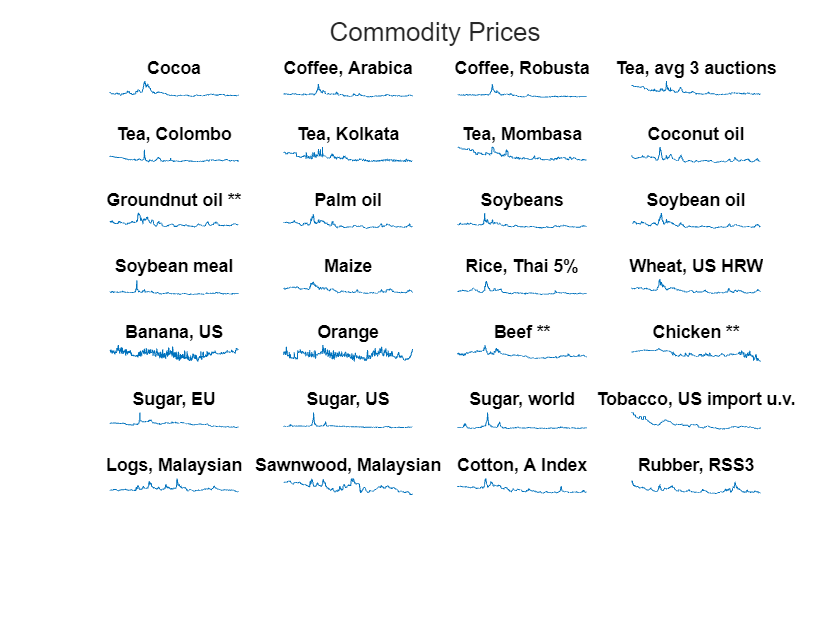

commodityNames = string(Prices.Properties.VariableNames);

figure

tiledlayout(8,4, "TileSpacing", "tight")

for commodity = 1:width(Prices)
    nexttile
    plot(Prices.Date, Prices{:, commodity})
    title(commodityNames(commodity))   
    axis off
end

sgtitle("Commodity Prices")

## Compute Commodity Price Returns

To further analyze the data in this example, you must work with the commodity price returns rather than the adjusted commodity prices. Use [tick2ret](docid:finance_ug.f5-738332) to convert the adjusted commodity prices $P_t$ to the return series $R_t$ as follows:


$$R_t = \frac{P_{t+1}}{P_t}-1, \quad t = 1, 2, 3, \dots$$


Returns = tick2ret(Prices);

## Visualize Commodity Price Returns

Plot each return series for soft commodities over time.

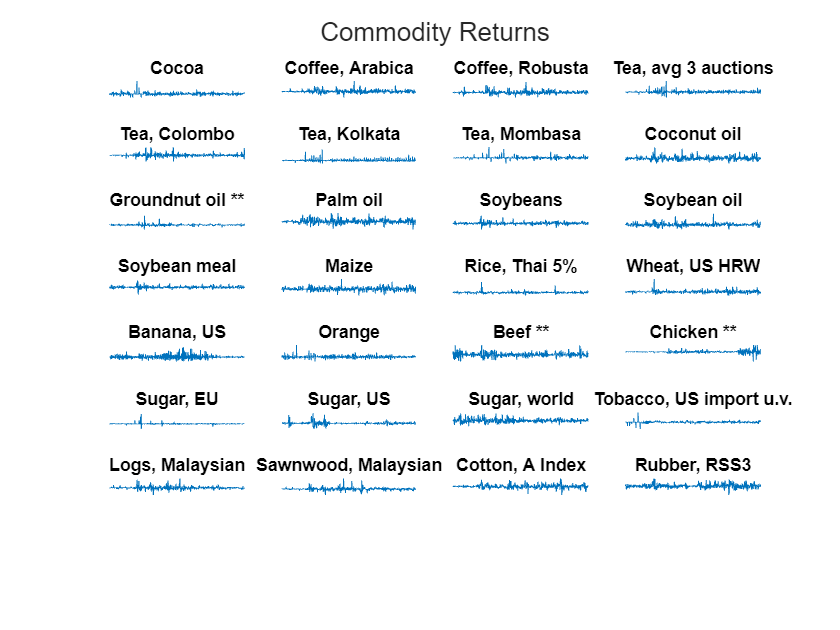

figure
tiledlayout(8,4, "TileSpacing", "tight")

for commodity = 1:width(Returns)
    nexttile
    plot(Returns.Date, Returns{:, commodity})
    title(commodityNames(commodity))
    axis off
end

sgtitle("Commodity Returns")

## **Decompose Prices and Cluster Commodities**

Decompose each commodity price series into a long-term trend, a seasonal component, and an irregular (or business cycle) component. This operation is an additive decomposition:


$$P_t = L_t + S_t + C_t, \quad t = 1, 2, 3, \dots,$$


where:

- $P_t$ is the commodity price series.

- $L_t$ is the long-term trend.

- $S_t$ is the seasonal component (which may be the sum of multiple seasonal trends).

- $C_t$ is the irregular component.

Based on the relative similarity of the irregular components of the commodity price series, you can cluster the commodities into groups using unsupervised machine learning techniques.

### Decompose Commodity Prices

Preallocate variables for the soft commodity series components.

numObservations = height( Prices );
numCommodities = width( Prices );

longTermComponent = NaN( numObservations, numCommodities );
seasonalComponent = NaN( numObservations, numCommodities );
irregularComponent = NaN( numObservations, numCommodities );
regularComponent = NaN( numObservations, numCommodities );

Create tiled layouts for the visualization. You can visualize the trend components (for example, the sum of $L_t$ and $S_t$) separately from the irregular components ($C_t$).

figure
tlTrend = tiledlayout(8,4, "TileSpacing", "tight");
title( tlTrend, "Trend Components" )

figure
tlIrregular = tiledlayout(8,4, "TileSpacing", "tight");
title( tlIrregular, "Irregular Components")

For each soft commodity price series, perform the trend decomposition by using [trenddecomp](docid:matlab_ref.mw_a3494fa6-7826-4590-ac4d-5335c011c443).

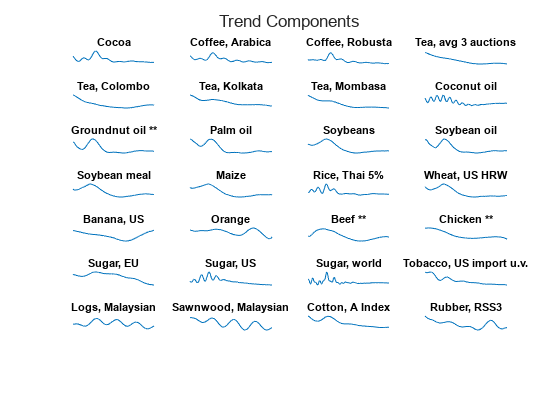

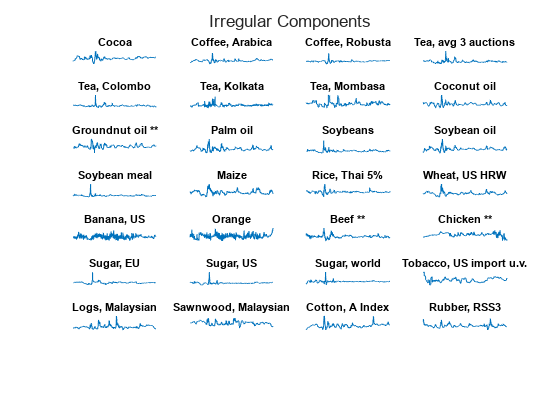

for k = 1:numCommodities

    % Decompose the price series and store the results. This process might identify 
    % more than one seasonal component, so sum the resulting matrix of seasonal 
    % components to obtain the overall seasonal trend.
    [L, S, C] = trenddecomp( Prices{:, k} );
    longTermComponent(:, k) = L;
    seasonalComponent(:, k) = sum( S, 2 );
    irregularComponent(:, k) = C;
    regularComponent(:, k) = longTermComponent(:, k) + seasonalComponent(:, k);

    % Add the components to the visualization.
    nexttile(tlTrend)
    plot(Prices.Date, regularComponent(:, k) )
    title(commodityNames(k))
    axis off

    nexttile(tlIrregular)
    plot(Prices.Date, irregularComponent(:, k))
    title(commodityNames(k))
    axis off

end

From the trend decomposition and by inspecting the series $L_t+S_t$ for each commodity, you can see that most commodities show a long-term decrease in price over recent decades, followed by a more recent upturn in the price. 

Some exceptions, such as the series *Sugar, EU*, show a long-term downward trend. 

Some commodities also appear to have gone through periods of high seasonal volatility, such as the two coffee price series. Banana and orange prices appear to be more susceptible to seasonal volatility. Chicken prices exhibit seasonal volatility that has increased in the last few years.

### Cluster Commodities Based on Similarity in Irregular Component

After removing the long-term and seasonal components from the price series, you are left with the irregular component $C_t$, given by

$C_t = P_t - L_t - S_t$.

The $C_t$ component represents the business cycle component in the soft commodity time series and this series is affected by short-term market conditions. This component provides a fairer basis for comparing the soft commodity prices because both the long-term price trends and the seasonal trends are removed.

Compute the pairwise distances between the irregular components using the correlation distance metric $d$. This metric is defined by

$d(s_1, s_2) = 1-\rho(s_1, s_2)$, where $\rho(s_1, s_2)$ is the linear correlation coefficient between the two time series $s_1$ and $s_2$.

irregularCorrDistances = pdist( irregularComponent.', "correlation" );

Use [linkage](docid:stats_ug.bssoowt-1) to perform hierarchical clustering using the correlation distances. The `complete` method uses the largest distance between commodities in the two clusters.

irregularComponentLinkage = linkage( irregularCorrDistances, "complete" );

Create a [dendrogram](docid:stats_ug.btk0xou) to visualize the linkage.

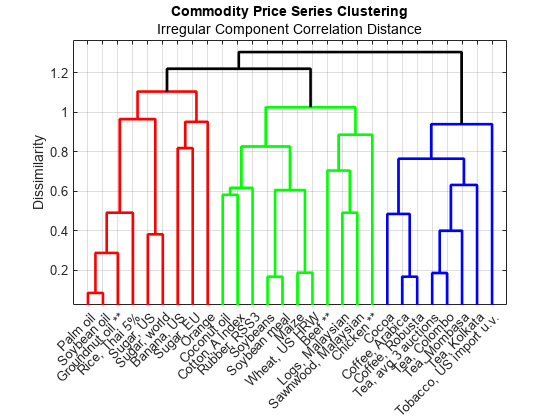

figure
h = dendrogram( irregularComponentLinkage, numCommodities, ...
    "Labels", commodityNames, ...
    "ColorThreshold", 1.2 );
ylabel( "Dissimilarity" )
title( "Commodity Price Series Clustering" )
subtitle( "Irregular Component Correlation Distance" )
set( h, "LineWidth", 2 )
xtickangle( 45 )
grid( "on" )
box( "on" )

Cluster the commodities into five groups based on their similarity obtained from this dendrogram.

numClusters = 3;
Group = cluster( irregularComponentLinkage, "maxclust", numClusters );
Commodity = string( commodityNames.' );
clusteredCommodities = table( Commodity, Group );
commoditiesByCluster = sortrows( clusteredCommodities, "Group" );
disp( commoditiesByCluster )

            Commodity            Group
    _________________________    _____

    "Coconut oil"                  1  
    "Soybeans"                     1  
    "Soybean meal"                 1  
    "Maize"                        1  
    "Wheat, US HRW"                1  
    "Beef **"                      1  
    "Chicken **"                   1  
    "Logs, Malaysian"              1  
    "Sawnwood, Malaysian"          1  
    "Cotton, A Index"              1  
    "Rubber, RSS3"                 1  
    "Groundnut oil **"             2  
    "Palm oil"                     2  
    "Soybean oil"                  2  
    "Rice, Thai 5%"                2  
    "Banana, US"                   2  
    "Orange"                       2  
    "Sugar, EU"                    2  
    "Sugar, US"                    2  
    "Sugar, world"                 2  
    "Cocoa"                        3  
    "Coffee, Arabica"             

### Cluster Commodities Based on Similarity in Regular Component

The regular component is the sum of the long-term and seasonal trends $L_t+S_t$, and is equal to $P_t-C_t$, the commodity price series without its irregular (business cycle) component.

Evaluate the pairwise distances and the corresponding linkage.

regularCorrDistances = pdist( regularComponent.', "correlation" );
regularComponentLinkage = linkage( regularCorrDistances, "complete" );

Create a [dendrogram](docid:stats_ug.btk0xou) to visualize the linkage, and then select a threshold to achieve three clusters.

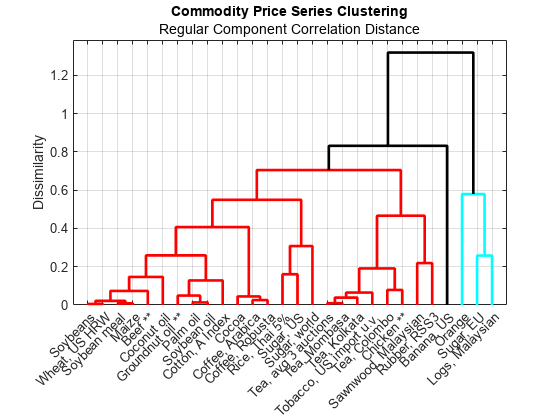

figure
h = dendrogram( regularComponentLinkage, numCommodities, ...
    "Labels", commodityNames, ...
    "ColorThreshold", 0.8 );
ylabel( "Dissimilarity" )
title( "Commodity Price Series Clustering" )
subtitle( "Regular Component Correlation Distance" )
set( h, "LineWidth", 2 )
xtickangle( 45 )
grid( "on" )
box( "on" )

You might expect the volatility in the commodities to manifest itself in the irregular component, rather than the regular component. For this reason, continue with the clusters identified by performing hierarchical clustering on the irregular components of the commodity price series. However, clustering on the regular components provides a useful grouping of the commodities based on their combined long-term and seasonal trends. From the dendrogram, you can see that both oranges and bananas have a dissimilar regular profile to the other commodities.

### Visualize Clusters in 3D

Embed the commodities in a lower-dimensional space by using classical multi-dimensional scaling using [cmdscale](docid:stats_ug.brx09qj-395).

lowerDim = 3;
Y = cmdscale( irregularCorrDistances, lowerDim );

Visualize the embedding. Add the convex hull of each group using [convhull](docid:matlab_ref.f80-999588) to illustrate the different groupings in 3-dimensional space.

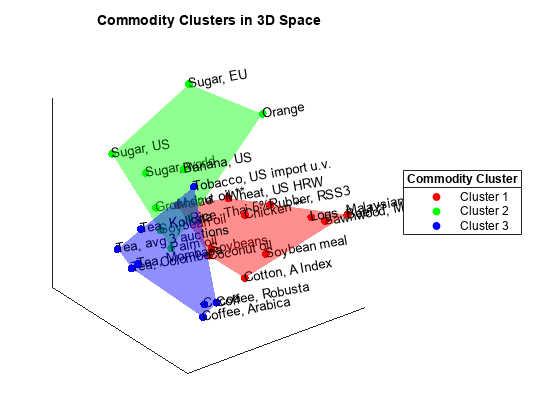

figure
view( 3 )
clusterColors = hsv( numClusters );
colormap( clusterColors )
hold( "on" )

for k = 1:numClusters
    % Extract coordinate data for the current group.
    idx = clusteredCommodities.Group == k;
    clusterx = Y(idx, 1);
    clustery = Y(idx, 2);
    clusterz = Y(idx, 3);
    color = clusterColors(k, :);
    % Evaluate the convex hull.
    ch = convhull( clusterx, clustery, clusterz );
    % Visualize the convex hull, its vertices (the commodities), and create
    % text labels.
    trisurf( ch, clusterx, clustery, clusterz, ...
        "FaceColor", clusterColors(k, :), ...
        "FaceAlpha", 0.25, ...
        "EdgeColor", "none", ...
        "HandleVisibility", "off" )
    scatter3( clusterx, clustery, clusterz, ...
        [], clusterColors(k, :), "filled", "DisplayName", "Cluster " + k )
    text( clusterx, clustery, clusterz, ...
        clusteredCommodities.Commodity(idx), "Rotation", 10 )
end

xticks( [] )
yticks( [] )
zticks( [] )
title( "Commodity Clusters in 3D Space" )
lg = legend( "Location", "eastoutside" );
title( lg, "Commodity Cluster" )

## **Estimate Nonparametric Volatility**

Obtain a nonparametric volatility estimate for each soft commodity series using an exponentially weighted moving average (EWMA).

To estimate the underlying volatility of a time series using an EWMA model, let$$\{r_n\}$$denote the sequence of commodity returns and let$$\{y_n\}$$ be the sequence of EWMA estimates for the instantaneous variance. The difference equation for computing the sequence $\{y_n\}$ is as follows:


$$y_1 =r_1^2 ,\;\;\;\;\;\;\;\;\;\;y_n =\lambda y_{n-1} +\left(1-\lambda \right)r_n^2 ,\;\;\;\;\;\;\;\;\lambda \in \;\left\lbrack 0,1\right\rbrack ,\;\;\;\;\;n\ge 2$$


- Here, $$\lambda$
$ is a scalar smoothing parameter chosen from the interval $$[0, 1]$$. 

- In many typical applications, $0.90\leq \lambda\leq 0.99$. In this example, you take $\lambda = 0.94$.

- As $\lambda$ increases, the influence of the previous moving average estimate ($y_{n-1}$) on the current variance estimate ($y_n$) increases, and the influence of the current squared return ($r_n^2$) decreases. 

- If $\lambda$ is close to `1`, then the influence of the current squared return value $r_n^2$ is negligible in the moving average and $y_{n-1}$ dominates. If $\lambda$ is close to `0`, then the current squared return value $r_n^2$ dominates and $y_{n-1}$ is negligible.

This example uses the *square* of the commodity returns in the EWMA computation because you estimate the instantaneous *variance* of the portfolio return series, from which you take the square root to obtain estimates for the instantaneous *volatility* (standard deviation).

### Compute Exponentially Weighted Moving Averages

Define the smoothing parameter $\lambda$.

lambda = 0.94;

Standard form for a filter in MATLAB® is the following:


$$a_0y_n = b_0x_n+b_1x_{n-1}+\dots +b_kx_{n-k} - a_1y_{n-1}-\dots -a_{n-\ell}y_{n-\ell}$$


where $\mathbf{a}=[a_0, a_1, a_2, a_{n-\ell}]$ and $\mathbf{b}=[b_0, b_1, \dots, b_k]$ are the filter coefficients. For more information, see [filter](docid:matlab_ref.bt_vs4t-1).

Write the EWMA filter coefficients in standard form:


$$ 1 y_n + (-\lambda)y_{n-1} = (1-\lambda)r_n^2$$


Here, you have $\mathbf{a}=[1, -\lambda]$ and $\mathbf{b}=[1-\lambda]=1-\lambda$.

a = [1, -lambda];
b = 1 - lambda;

Compute the instantaneous variance and volatility estimates.

instantVariance = filter(b, a, Returns.Variables.^2);
InferredVolatility = sqrt( instantVariance );

Create a [timetable](docid:matlab_ref.bvdhiqg) containing the estimated volatilities.

InferredVolatility = array2timetable( InferredVolatility, ...
    "VariableNames", commodityNames, ...
    "RowTimes", Returns.Date );
InferredVolatility.Properties.DimensionNames(1) = "Date";

### Visualize Estimated Volatility Series

Select one of the soft commodities and visualize that commodity's price series, return series, and the inferred volatility.

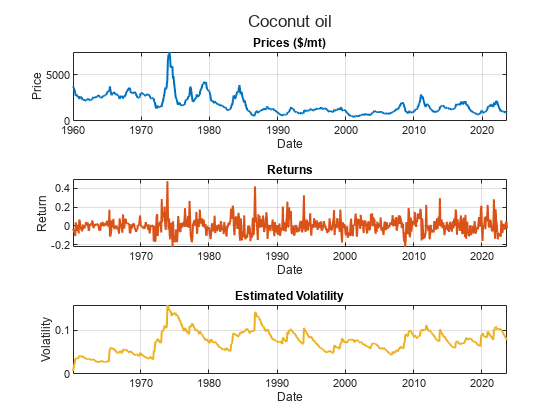

chosenCommodity = commodityNames(8);

figure
tiledlayout( 3, 1 )
sgtitle( chosenCommodity )
corder = colororder();

nexttile
plot( Prices.Date, Prices.(chosenCommodity{1}), ...
    "LineWidth", 1.5, "Color", corder(1, :) )
xlabel( "Date" )
ylabel( "Price" )
units = Prices.Properties.VariableUnits(chosenCommodity);
title( "Prices " + units )
grid on

nexttile
plot( Returns.Date, Returns.(chosenCommodity{1}), ...
    "LineWidth", 1.5, "Color", corder(2, :) )
xlabel( "Date" )
ylabel( "Return" )
title( "Returns" )
grid on

nexttile
plot( InferredVolatility.Date, InferredVolatility.(chosenCommodity{1}), ...
    "LineWidth", 1.5, "Color", corder(3, :) )
xlabel( "Date" )
ylabel( "Volatility" )
title( "Estimated Volatility" )
grid on

### Use Estimated Volatility to Perform Factor Analysis on Commodities

Applying factor analysis is another technique for grouping the commodities into clusters, based on the estimated volatility profiles.

Factor analysis assumes the existence of a certain number of hidden or latent factors underlying the data. If you hypothesize that the volatility in the soft commodities is driven by a smaller number of latent factors (such as external market conditions), then factor analysis provides one approach for understanding these hidden factors. For more information on factor analysis, see [factoran](docid:stats_ug.brx09qp-705).

numLatentFactors = 3;
loadings = factoran( InferredVolatility.Variables, numLatentFactors );

Visualize the factor loadings by using [heatmap](docid:matlab_ref.bvh0gj7-1).

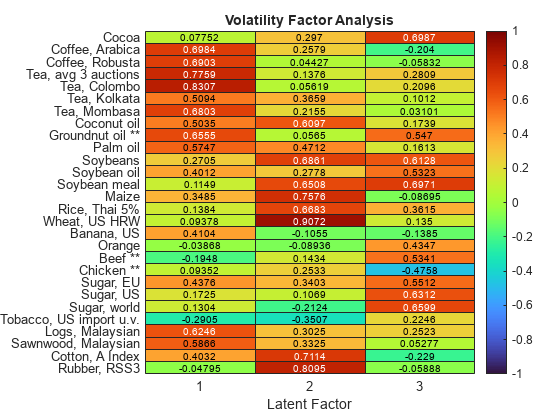

figure
heatmap( 1:numLatentFactors, commodityNames, loadings, ...
    "Colormap", turbo, ...
    "ColorLimits", [-1, 1] )
xlabel( "Latent Factor" )
title( "Volatility Factor Analysis" )

Using [heatmap](docid:matlab_ref.bvh0gj7-1) again, visualize the strongest association with each latent factor for each factor.

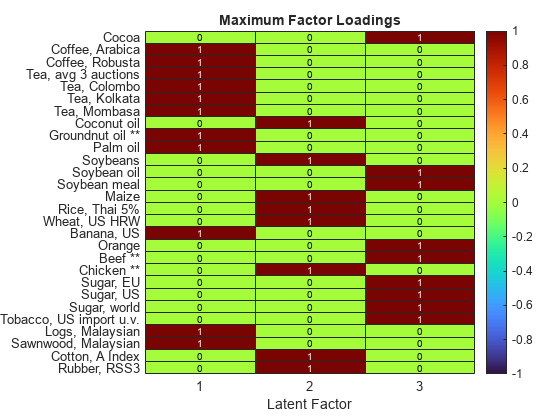

maxIdx = double( loadings == max( loadings, [], 2 ) );
figure
heatmap( 1:numLatentFactors, commodityNames, maxIdx, ...
    "Colormap", turbo, ...
    "ColorLimits", [-1, 1] )
xlabel( "Latent Factor" )
title( "Maximum Factor Loadings" )

Looking at the **Maximum Factor Loadings** heatmap, you can see:

- Coffee, tea, groundnut oil, palm oil, bananas, and wood have a strong association with latent factor 1. 

- Coconut oil, soybeans, maize, rice, wheat, chicken, cotton, and rubber have a strong association with latent factor 2.

- Latent factor 3 is associated with cocoa, soybean oil, soybean meal, oranges, beef, shrimps, sugar, and tobacco.

- The strongest negative association in the loadings matrix is chicken with latent factor 3. Other loadings for chicken are relatively low, indicating that chicken volatility is an outlier in this data set, as you can also observe by using other methods.

## **Estimate Model-Based Volatility**

One disadvantage of using the exponentially weighted moving average for volatility estimation is that it does not provide volatility forecasts. However, you can use a model-based approach to create volatility forecasts. This example uses [arima](docid:econ_ug.bs6v6be) and [garch](docid:econ_ug.buochls) time-series models.

### Compute Principal Components of Inferred Volatility

First, use [normalize](docid:matlab_ref.mw_3d2d97f9-e35e-4f03-9aac-6ffe49f1400a) on the volatility series and store the mean and standard deviation for later use.

[normalizedVolatility, mu, sigma] = normalize( InferredVolatility.Variables, "zscore" );

Next, compute the principal components by using [pca](docid:stats_ug.bth9ibe).

[coeffs, scores, eigVals] = pca( normalizedVolatility );

Visualize the eigenvalues of the covariance matrix of the normalized volatilities.

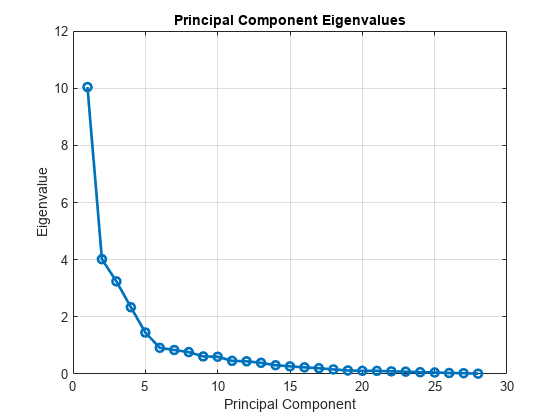

figure
plot( eigVals, "o-", "LineWidth", 2 )
xlabel( "Principal Component" )
ylabel( "Eigenvalue" )
title( "Principal Component Eigenvalues" )
grid( "on" )

You can see that most of the variance in the data is captured by the first few principal components.

Visualize the first two principal components.

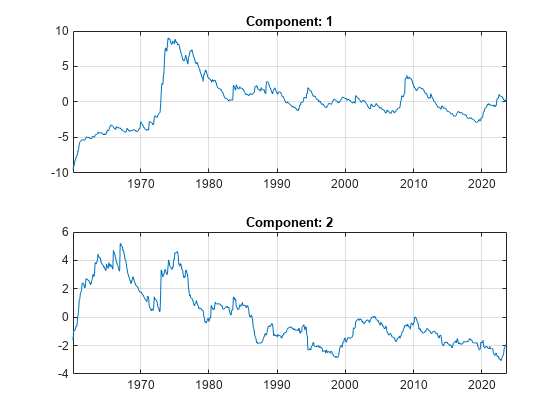

numComponents = 2;

figure
tiledlayout( "flow" )

for k = 1:numComponents
    nexttile
    plot( InferredVolatility.Date, scores(:, k ) )
    title( "Component: " + k )
    grid( "on" )
end

### Model Principal Components

Rather than creating many separate time-series models for each soft commodity, you can take an efficient approach by building models for only the first few principal components. You can then back-transform forecasts from these models into the original domain. 

Create and fit an [arima](docid:econ_ug.bs6v6be) time-series model for the first principal component.

firstComponent = scores(:, 1);

firstComponentModel = arima( "ARLags", 1, ...
    "MALags", 1, ...
    "Distribution", "t", ...
    "Variance", garch( 1, 1 ) );
firstComponentModel = estimate( firstComponentModel, firstComponent );

 
    ARIMA(1,0,1) Model (t Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.063238       0.006214       -10.177      2.5191e-24
    AR{1}         0.98215      0.0019302        508.82               0
    MA{1}         0.15671       0.031714        4.9412      7.7629e-07
    DoF            2.5091        0.24115        10.405      2.3521e-25

 
 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    _

Create and fit an [arima](docid:econ_ug.bs6v6be) time-series model for the second principal component.

secondComponent = scores(:, 2);
secondComponentModel = arima("ARLags", 1, ...
    "MALags", 1, ...
    "Distribution", "t", ...
    "Variance", garch( "ARCHLags", 1, ...
    "Constant", 0.01, ...
    "GARCHLags", 1 ) );
secondComponentModel = estimate( secondComponentModel, secondComponent );

 
    ARIMA(1,0,1) Model (t Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    -0.025173      0.0043829       -5.7433       9.2839e-09
    AR{1}         0.98224       0.002459        399.45                0
    MA{1}        0.077561       0.025207        3.0769        0.0020913
    DoF            2.1625       0.086605         24.97      1.3059e-137

 
 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    <s

### Create Simulated Component Values from Fitted Models

Use [simulate](docid:econ_ug.bs678hw) to create the simulated component values from the fitted models.

numForecastSteps = 60;
simFirstComponent = simulate( firstComponentModel, numForecastSteps, "Y0", firstComponent );
simSecondComponent = simulate( secondComponentModel, numForecastSteps, "Y0", secondComponent );
simComponents = [simFirstComponent, simSecondComponent];

### Back-Transform Simulated Component Values

Transform the simulation results in the principal component domain back to the original volatility domain, adjusting for the normalization step performed in Compute Principal Components of Inferred Volatility. Since you have modeled only the first two principal components, this transformation is an approximation to the volatility. Modeling more of the principal components would lead to a more accurate volatility approximation at the cost of more modeling, simulation, and execution time.

approxVolatility = mu + sigma .* (simComponents * coeffs(:, 1:2).');
approxVolatility = [InferredVolatility{end, :}; approxVolatility];

Convert the volatility approximations to the timetable format.

simDates = InferredVolatility.Date(end) + calmonths(0:numForecastSteps).';
approxVolatility = array2timetable( approxVolatility, ...
    "RowTimes", simDates, "VariableNames", commodityNames );
approxVolatility.Properties.DimensionNames(1) = "Date";

### Visualize Volatility Simulation Results

In the **Model-Based Volatility Simulation** plot, the blue line indicates historical data and the red line indicates the simulated volatility moving into the future.

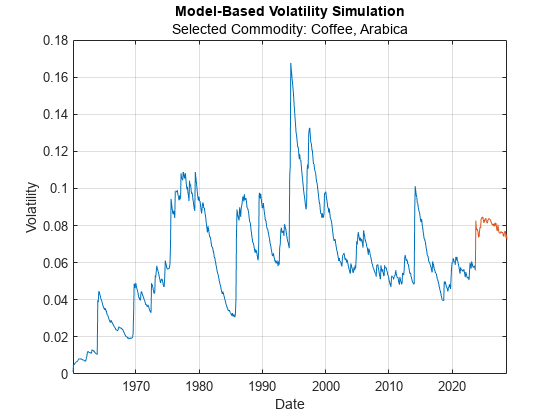

selectedCommodity = commodityNames(2);

figure
plot( InferredVolatility.Date, InferredVolatility.(selectedCommodity) )
hold on
plot( approxVolatility.Date, approxVolatility.(selectedCommodity) )
xlabel( "Date" )
ylabel( "Volatility" )
title( "Model-Based Volatility Simulation" )
subtitle( "Selected Commodity: " + selectedCommodity )
grid on

## References

[1] The World Bank: Commodity Monthly Prices, located at: [https://www.worldbank.org/en/research/commodity-markets](https://www.worldbank.org/en/research/commodity-markets) and licensed under [CC BY 4.0 Deed | Attribution 4.0 International | Creative Commons](https://creativecommons.org/licenses/by/4.0/).

[2] U.S. Bureau of Labor Statistics, Consumer Price Index for All Urban Consumers: Purchasing Power of the Consumer Dollar in U.S. City Average [CUUR0000SA0R]. Available at [https://beta.bls.gov/dataViewer/view/timeseries/CUUR0000SA0R](https://beta.bls.gov/dataViewer/view/timeseries/CUUR0000SA0R). Data provided by the U.S. Bureau of Labor Statistics through the BLS Data Viewer at BLS.gov. BLS.gov cannot vouch for the data or analyses derived from these data after the data have been retrieved from BLS.gov.

## Local Functions

% Import the commodity data.

function Prices = importCommodityData(filename)

% Detect the import options for the file CMO-Historical-Data-Monthly.xlsx.
opts = detectImportOptions(filename, ...
    "Sheet", "Monthly Prices", ...
    "VariableNamingRule", "preserve", ...
    "TextType", "string");

% Rename the first variable to Date.
opts.VariableNames = replace(opts.VariableNames, "Var1", "Date");

% Ensure that all variables apart from the first are numeric.
numVars = length(opts.VariableTypes);
opts.VariableTypes = ["string", repmat("double", 1, numVars - 1)];

% Ensure that the variable units are imported in addition to the data.
opts.VariableUnitsRange = "A6";

% Import the data.
Prices = readtable(filename, opts);

end % importCommodityData

*Copyright 2024 The MathWorks, Inc.*